# Allocating Resources After Hurricane Harvey

.

## Background and Scope

This report is generated to help an insurance company to decide where to send outside contractors to assist claim adjusters in the aftermath of the Hurricane Harvey.

### Import the Data

After importing the storm events data file through a MATLAB generated import function called "importStormFile", I have filtered the data to only states which were directly affected by Hurricane Harvey. Some of these states are **Arkansas, Kentucky, Louisiana, Mississipi, North Carolina, Tennessee, and Texas.**

StormEvents_2017 = importStormFile("StormEvents_2017_finalProject.csv");
Harvey = StormEvents_2017(ismember(StormEvents_2017.State,{'ARKANSAS','KENTUCKY', ...
    'LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS','ALABAMA', ...
    'FLORIDA','GEORGIA','SOUTH CAROLINA'}),:);


Since Hurricane Harvey related events occured only from the 17th of August to the 3rd of September, So we are analysing the data between these two dates, as shown in the Table.

Harvey = Harvey(ismember(Harvey.Month,{'August','September'}),:);
Harvey = sortrows(Harvey,'Begin_Date_Time');

Harvey = Harvey(Harvey.Begin_Date_Time >= '17-Aug-17 00:00:00' & ...
    Harvey.Begin_Date_Time <= '03-Sep-17 00:00:01',:);
Harvey(1:5:30,3:1:9)

ans = 6×7 table
        State         Year    Month        Event_Type         CZ_Name      Begin_Date_Time      Timezone
    ______________    ____    ______    _________________    _________    __________________    ________

    TEXAS             2017    August    Flash Flood          GRAYSON      17-Aug-17 04:30:00       -6   
    TEXAS             2017    August    Flash Flood          DALLAS       17-Aug-17 06:50:00       -6   
    KENTUCKY          2017    August    Thunderstorm Wind    PENDLETON    17-Aug-17 14:54:00       -5   
    NORTH CAROLINA    2017    August    Thunderstorm Wind    WILKES       17-Aug-17 18:28:00       -5   
    NORTH CAROLINA    2017    August    Thunderstorm Wind    WILKES       17-Aug-17 18:53:00       -5   
    TEXAS 

The storm events from 17th August to the 3rd of September can be seen in the following geodensity plot.

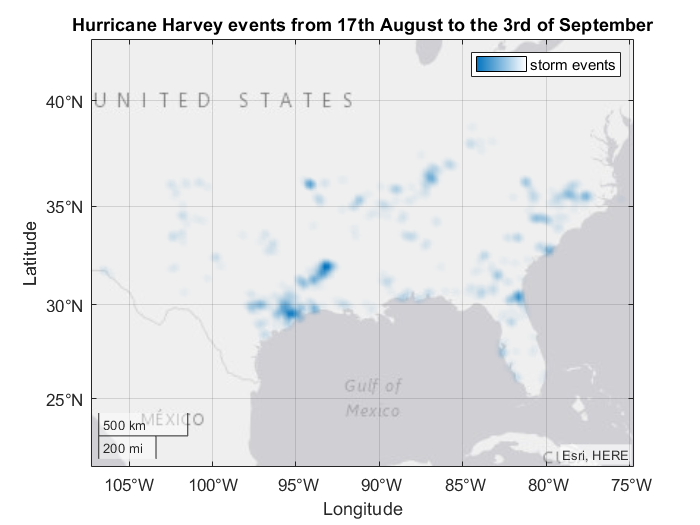

geodensityplot(Harvey.Begin_Lat,Harvey.Begin_Lon)
legend('storm events')
title("Hurricane Harvey events from 17th August to the 3rd of September")

### Two States Most Impacted by Harvey

The two states most impacted by Hurricane Harvey in term of total Property Cost estimated. 275 and 86 storm events occured in the states of Texas and Louisiana, respectively. Sum of property cost in these two states are $77427 Millions and $75.277 Millions for the states of Texas and Louisiana, respectively.

total_cost=groupsummary(Harvey,"State","sum","Property_Cost");
total_cost = sortrows(total_cost,'sum_Property_Cost','descend');
Impacted_states=total_cost(1:2,:)

Impacted_states = 2×3 table
      State      GroupCount    sum_Property_Cost
    _________    __________    _________________

    TEXAS           275           7.7427e+10    
    LOUISIANA        86           7.5277e+07    


### Table of Events for Two Most Impacted States

Few rows of the table of two most impacted states are shown below. This table includes only the states of Texas and Louisiana.

two_states = Harvey(ismember(Harvey.State,{'LOUISIANA','TEXAS'}),:);
two_states = sortrows(two_states,'Deaths_Direct','descend');
head(two_states)

ans = 8×24 table
    EpisodeID      Event_ID     State    Year    Month       Event_Type        CZ_Name       Begin_Date_Time      Timezone      End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                    

## Visualizations

### Figure of Event Types

The following Histogram shows the different types of events occured during hurricane Harvey in the most impacted states of Texas and Louisiana. The most frequent event was Flash Floods which occured 179 times.

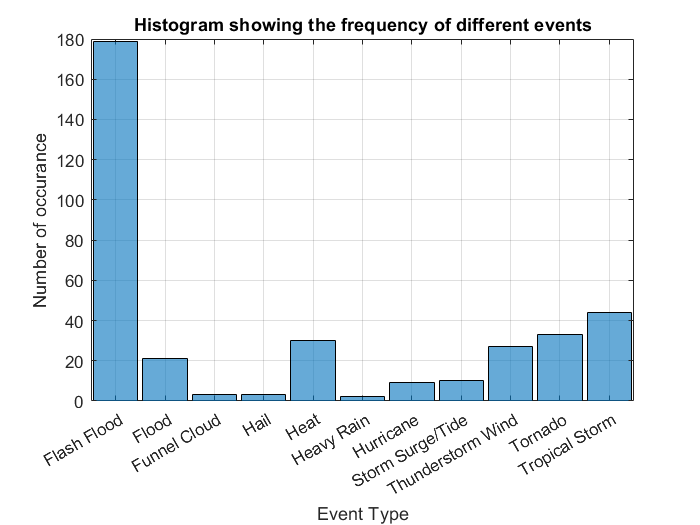

%filtering the event types which didn't occure, or their frequency is 0.
two_states.Event_Type = removecats(two_states.Event_Type);
histogram(two_states.Event_Type)
grid on
title('Histogram showing the frequency of different events')
xlabel('Event Type')
ylabel('Number of occurance')

The following heatmap shows count of Event types vs States of Texas and Louisiana.

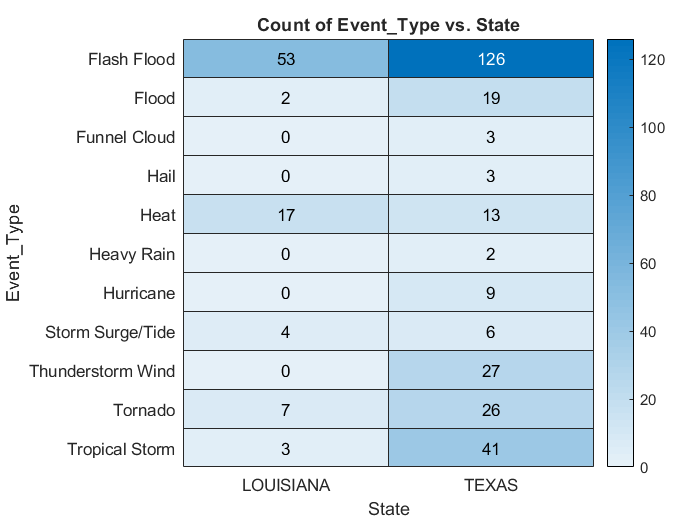

two_states.State=removecats(two_states.State);
heatmap(two_states,"State","Event_Type")

### Figure of Event Locations

following is the geocatter plot to show the storm event locations in the states of Texas and Louisiana.

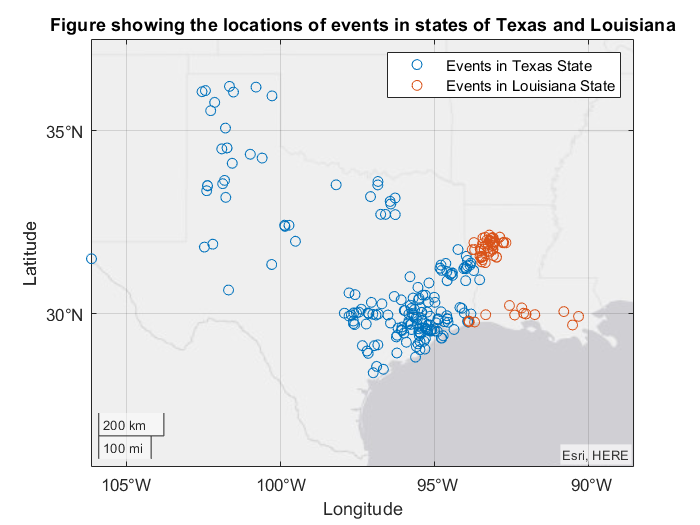

texas=two_states.State=="TEXAS";
geoscatter(two_states.Begin_Lat(texas),two_states.Begin_Lon(texas))
geolimits([25.6 37.4],[-106.09 -88.60])

hold on
lsiana=two_states.State=="LOUISIANA";
geoscatter(two_states.Begin_Lat(lsiana),two_states.Begin_Lon(lsiana))
legend({'Events in Texas State','Events in Louisiana State'})
hold off

title('Figure showing the locations of events in states of Texas and Louisiana')

## Analysis

### Three Counties with Most Events in Texas State

The three counties with most events in Texas are shown in following table. The county **Harris** had the largest number of events which is 21.


state_1 = two_states(two_states.State == 'TEXAS',:);
state1_3count=groupcounts(state_1,"CZ_Name");
state1_3count = sortrows(state1_3count,'GroupCount','descend');
state1_3count=state1_3count(1:3,:)

state1_3count = 3×2 table
     CZ_Name     GroupCount
    _________    __________

    HARRIS           21    
    GALVESTON        17    
    FORT BEND        13    


### Three Counties with Most Events in Louisiana State

Natchitoches, Sabine and Red River are the counties with the most events in the state of Louisiana.

state_2 = two_states(two_states.State == 'LOUISIANA',:);
state2_3count=groupcounts(state_2,"CZ_Name");
state2_3count = sortrows(state2_3count,'GroupCount','descend');
state2_3count=state2_3count(1:3,:)

state2_3count = 3×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    


### Three Counties with Highest Property Cost in Texas State

The following table shows 3 counties with highest property cost in the Texas state. These counties are Galveston, Fort Bend and Montgomery with property cost of $20, $16.004 and $14 Billions, respectively. It is assumed that these costs are estimates from models.

Hproperty_s1=groupsummary(state_1,"CZ_Name","sum","Property_Cost");
Hproperty_s1 = sortrows(Hproperty_s1,'sum_Property_Cost','descend');
Hprop_s1c3=Hproperty_s1(1:3,:)

Hprop_s1c3 = 3×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    GALVESTON         17                2e+10    
    FORT BEND         13           1.6004e+10    
    MONTGOMERY         6              1.4e+10    


### Three Counties with Highest Property Cost in Louisiana State

The following table shows 3 counties with highest property cost in the Louisiana state. These counties are Calcasieu, Beauregard and Acadia with property cost of $60, $15 and $0.2 Millions, respectively. It is assumed that these costs are estimates from models.

Hproperty_s2=groupsummary(state_2,"CZ_Name","sum","Property_Cost");
Hproperty_s2 = sortrows(Hproperty_s2,'sum_Property_Cost','descend');
Hprop_s2c3=Hproperty_s2(1:3,:)

Hprop_s2c3 = 3×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    CALCASIEU         1                6e+07     
    BEAUREGARD        1              1.5e+07     
    ACADIA            1                2e+05     


## Conclusions and Recommendations

### Texas State

After analyzing the storm data, we know that the state of Texas is the most affected. a total of 275 events occured in the state during the hurricane Harvey. The number and Types of event can be seen in histogram in the visualization section. Most of the events occured in the Harris, Galveston, and Fort Bend counties. In terms of property cost, Texas state has a property cost of around $77 billion. Galveston, Fort Bend, and Montgomery are the three counties in the Texas state with the highest property cost of $20, $16.004, and $14 Billion, respectively.

### Louisiana State

The second most impacted state is the state of Louisiana. around 86 events occured in this state. Most of the events occured in the Natchitoches, Sabine, and Red River counties.In terms of property cost, this state has a property cost of around $75 million. Calcasieu, Beauregard, and Acadia are the three counties in the Louisiana state with the highest property cost of $60, $15, and $0.2 Million, respectively.

### Recommendations

It is recommended that the priority for the insurance company should be the states of Texas and Louisiana, with the state of Texas at the top. The company should send most of outside contractors to the Texas state with the priority in the counties of Galveston, Fort Bend, and Montgomery. For the state of Louisiana, the company should send outside contractors to the counties of Calcasieu, Beauregard, and Acadia. 